 x=readtable("../datos_maiz.csv");
 x

x = 10454×2 table
       Date         Last 
    ___________    ______

    29-Jun-2021       531
    28-Jun-2021     557.5
    25-Jun-2021       530
    24-Jun-2021    547.25
    23-Jun-2021    544.25
    22-Jun-2021    550.25
    21-Jun-2021    568.75
    18-Jun-2021     578.5
    17-Jun-2021       545
    16-Jun-2021    582.25
    15-Jun-2021    583.75
    14-Jun-2021     590.5
    11-Jun-2021       620
    10-Jun-2021       624
    09-Jun-2021       617
    08-Jun-2021       617


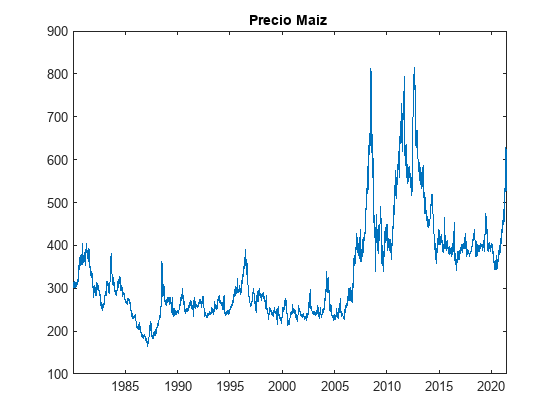

 plot(x.Date,x.Last)
 title("Precio Maiz ")

[imf,residual] = vmd(x.Last,NumIMF=9);

t = tiledlayout(3,3, ...
    TileSpacing="compact",Padding="compact");

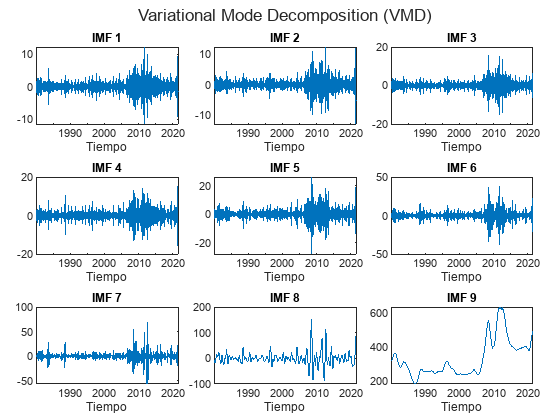

for n = 1:9
    nexttile(t)
    plot(x.Date,imf(:,n))
    title("IMF " + num2str(n))
    xlabel("Tiempo")

    fecha_formateada=datestr(x.Date, 'yyyy-mm-dd');
    DatosFinal=table(fecha_formateada,imf(:,n),'VariableNames',{'Fecha','Precio_Cierre'});
    nombre=sprintf("vmd_modes/modo_%d.csv",n);
    writetable(DatosFinal,nombre)
end
title(t,"Variational Mode Decomposition (VMD)")
saveas(gcf, 'imagenes/Descompocision VMD.png');

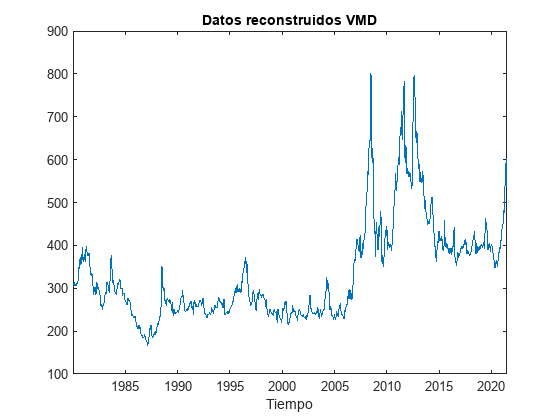


figure;
Datos_Limpios = sum(imf(:,6:9),2);
plot(x.Date,Datos_Limpios)
title("Datos reconstruidos VMD")
xlabel("Tiempo")
saveas(gcf, 'imagenes/Datos recosntruidos VMD.png');

fecha_formateada=datestr(x.Date, 'yyyy-mm-dd');
DatosFinal=table(fecha_formateada,Datos_Limpios,'VariableNames',{'Fecha','Precio_Cierre'});
writetable(DatosFinal,"VMD_datos.csv")